# Confidence Regions Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path. To do so you can navigate to the StatBainz folder and fun the function addSB2path.m. Alternatively you can fill in the directory and run the code below.

statsbrainz_directory_pathloc = 'fill me in';
addpath(genpath(statsbrainz_directory_pathloc));

## Surface Confidence regions

sb_dir = statbrainz_maindir;
path4gifti_L = [sb_dir, 'BrainImages/Gifti_files/S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, 'BrainImages/Gifti_files/S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
load([sb_dir,'BrainImages/Real_data/hcpWM_surface.mat'])

#### Generate data

FWHM = 10;
nsubj = 50;
data = srf_noise(hcp_srf.lh, FWHM, nsubj);

50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done


data = data./std(data(:));
data = data.*hcp_data_std.lh;
data = data + hcp_data_mean.lh;

## FDR cope sets

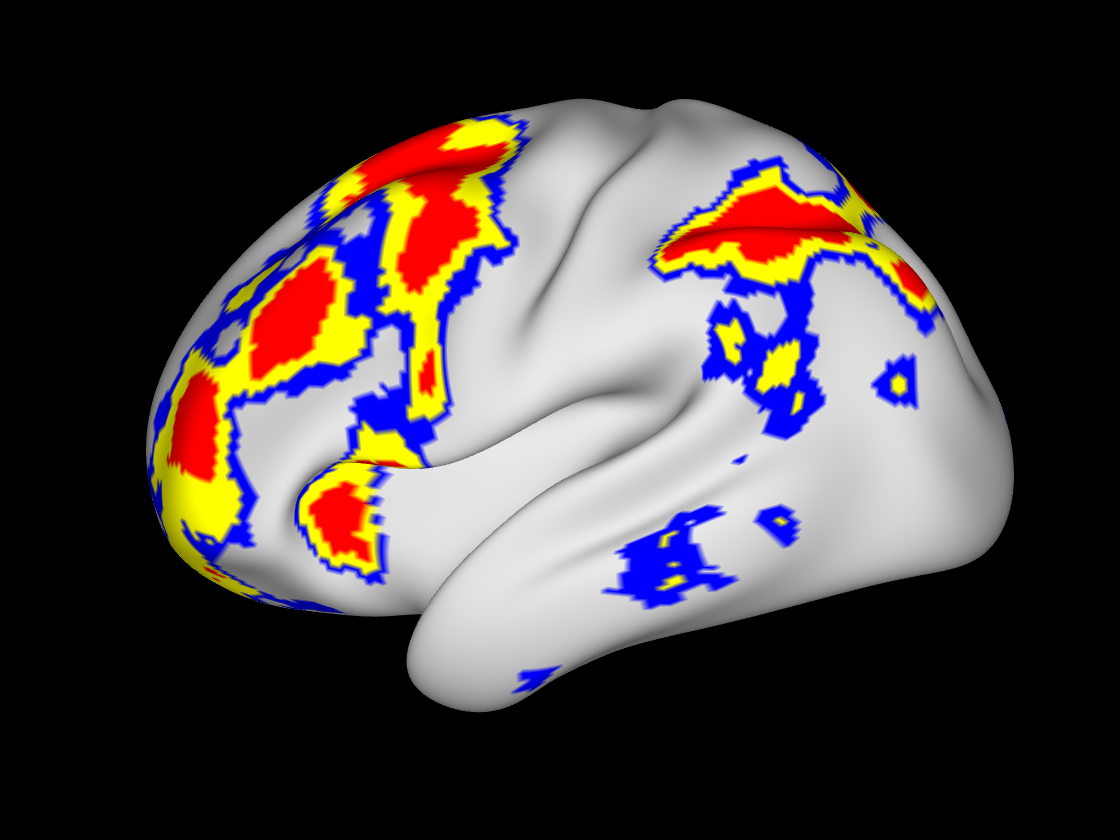

figure; set(gcf,'Visible','on')
c = 1;
[tstats, xbar] = mvtstat(data - c);
pvals = tstat2pval(nan2zero(tstats), 50 -1, 0);
upper_set = fdrBH( pvals );
lower_set = 1-fdrBH( 1 - pvals );
srf_cope_display(hcp_srf.lh,lower_set,upper_set, xbar, 0)

## Simultaneous Confidence Regions

[ lower_band, upper_band ] = scopes( data, 1000, 0.05, 1);

-------------------------------------------------------
fastperm progress: 100.0


c = 2;
[ lower_set, upper_set, contour ] = srf_scb2cope( hcp_srf.lh, lower_band, upper_band, xbar, c );
[ upper_set2, lower_set2, contour2 ] = srf_scb2cope( hcp_srf.lh, -lower_band, -upper_band, -xbar, c );

figure; clf; set(gcf,'Visible','on')
color_map1 = srf_colour(hcp_srf.lh, {lower_set, upper_set, contour}, {[1,0.5,0.5], [0.9,0,0], [1,1,0]}, 0);
color_map2 = srf_colour(hcp_srf.lh, {lower_set2, upper_set2, contour2}, {[1,0.5,0.5], [0.9,0,0], [1,1,0]}, 0);
%srfplot(hcp_srf.lh, color_map1)

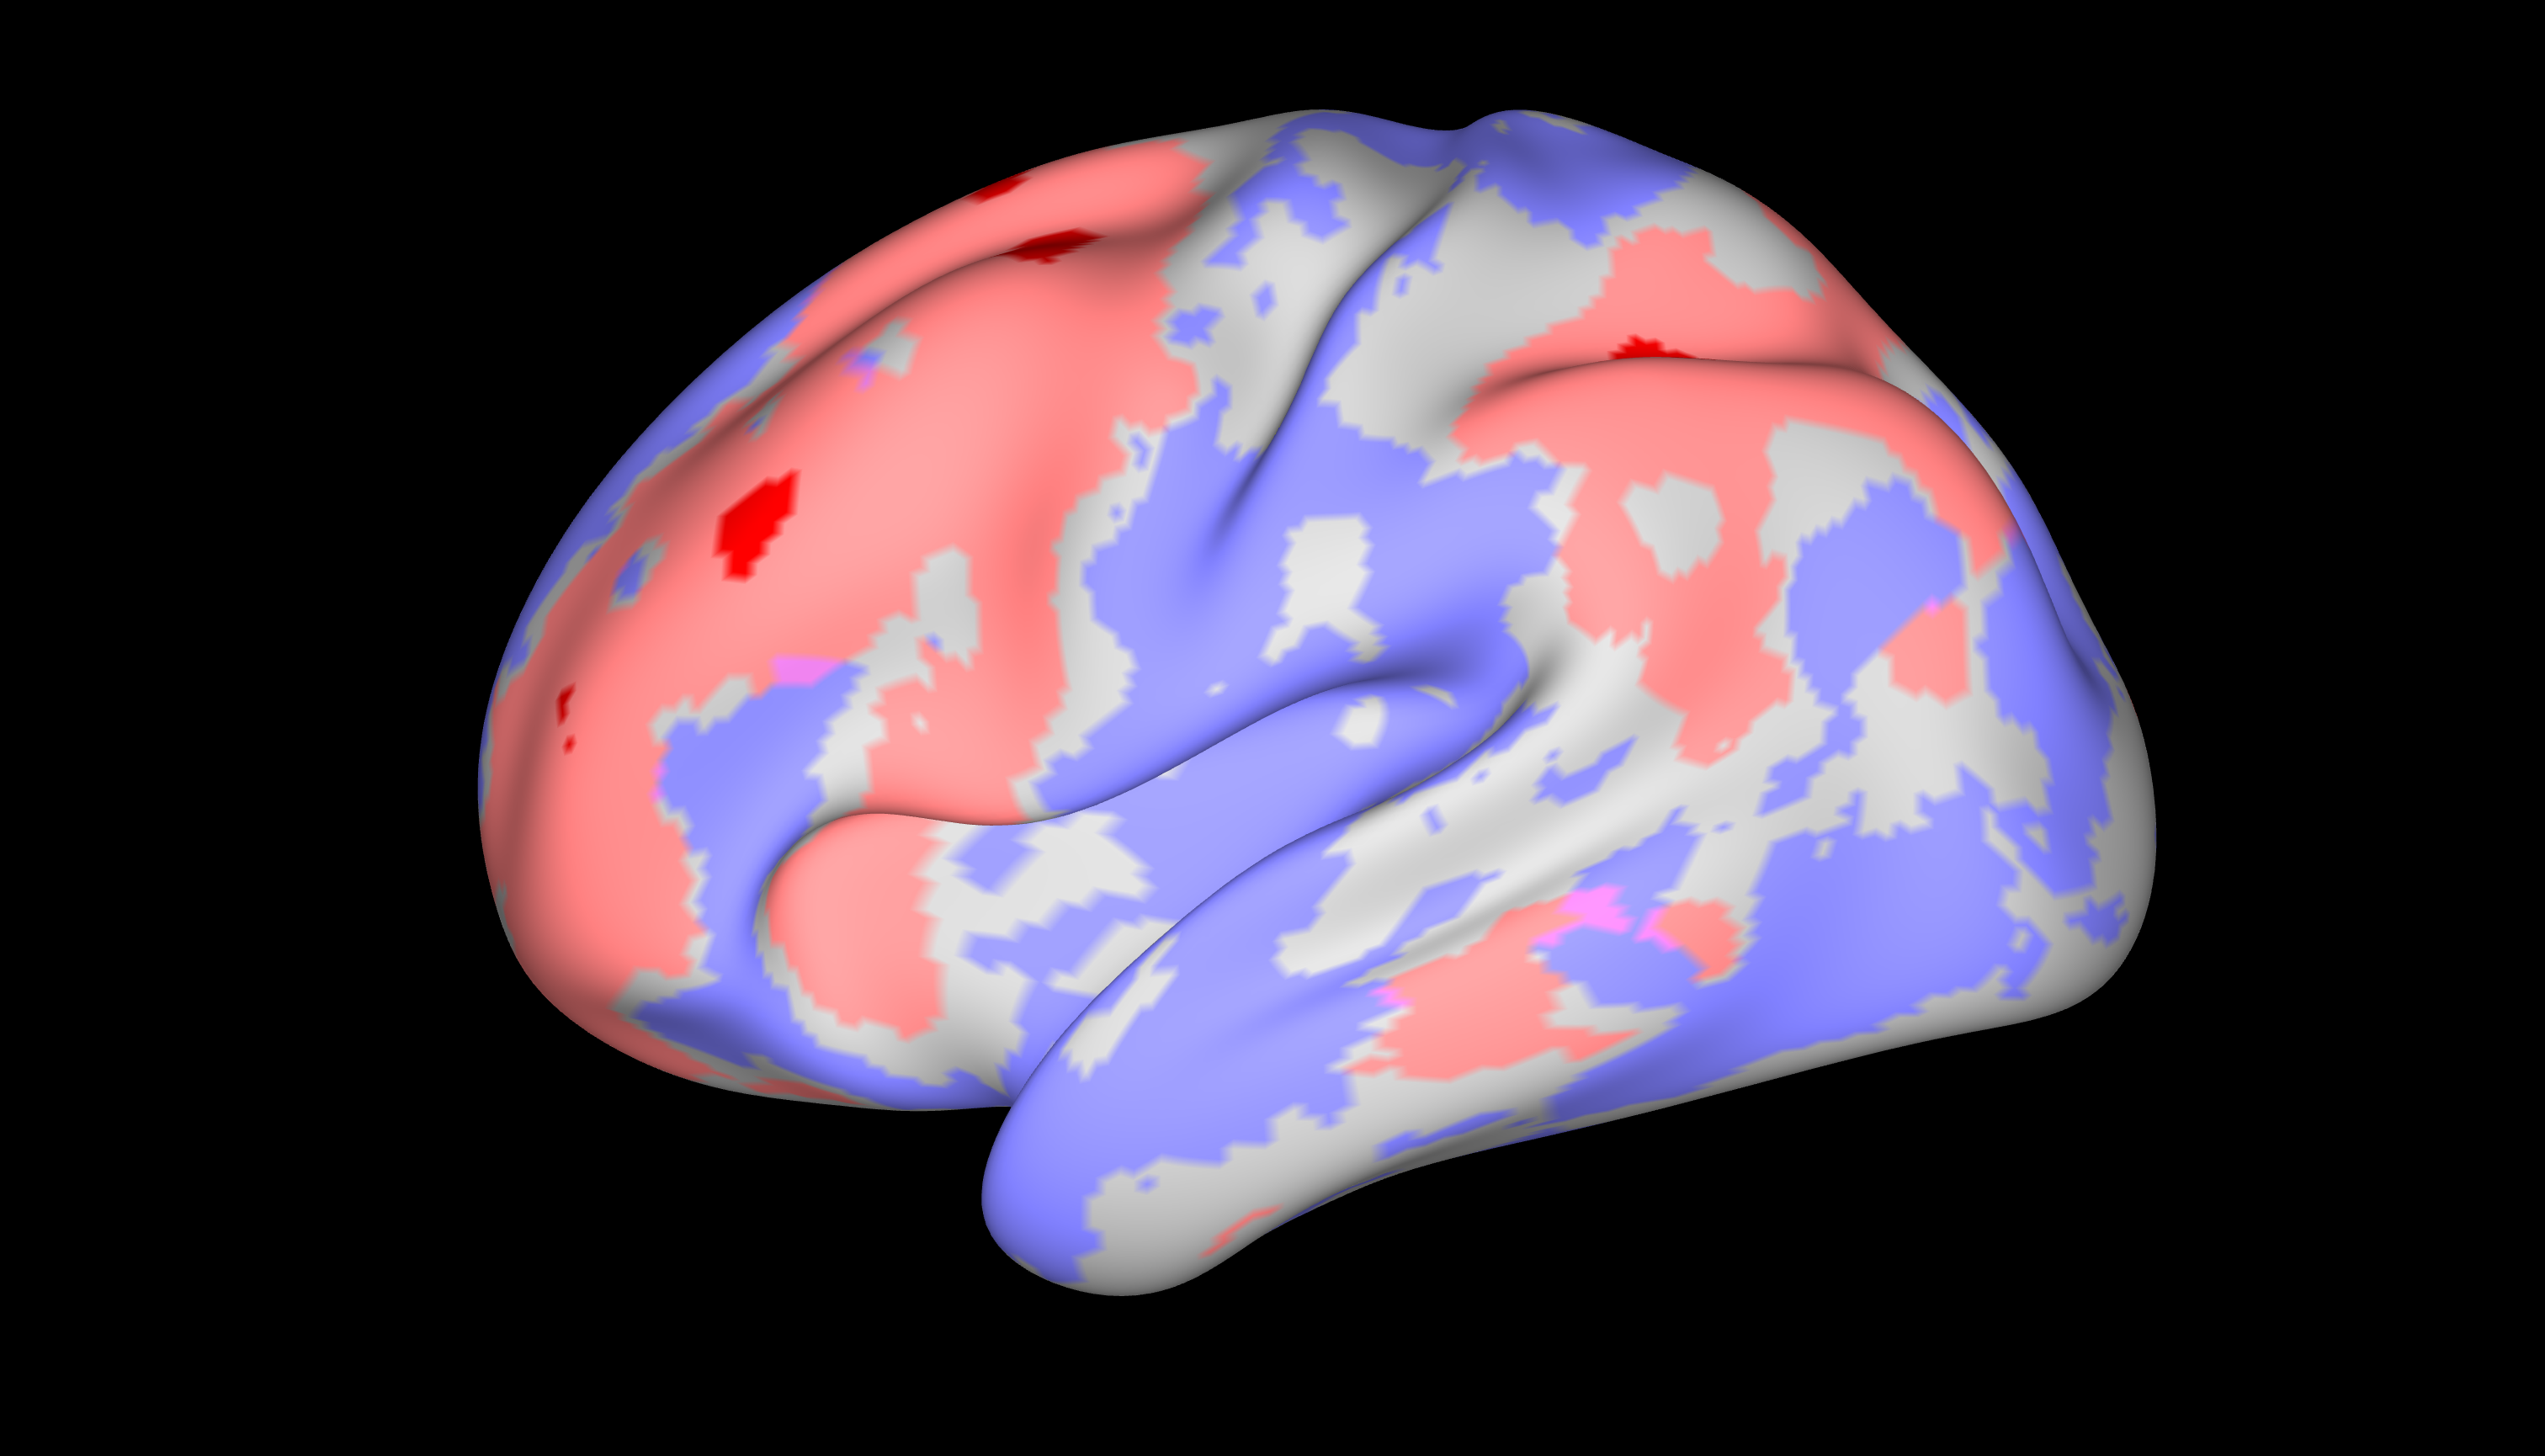

figure; set(gcf,'Visible','on')

lower_intersection = lower_set.*lower_set2 >0;
lower_just1 = lower_set - lower_intersection >0;
lower_just2 = lower_set2 - lower_intersection >0;

sets = {lower_intersection, lower_just1, lower_just2, upper_set, upper_set2};
colours = {[0.93 0.51 0.93]*0.9, [1,0.5,0.5], [0.5,0.5, 1], [0.9,0,0], [0,0,0.9]};
color_map = srf_colour(hcp_srf.lh, sets, colours);
srfplot(hcp_srf.lh, color_map)

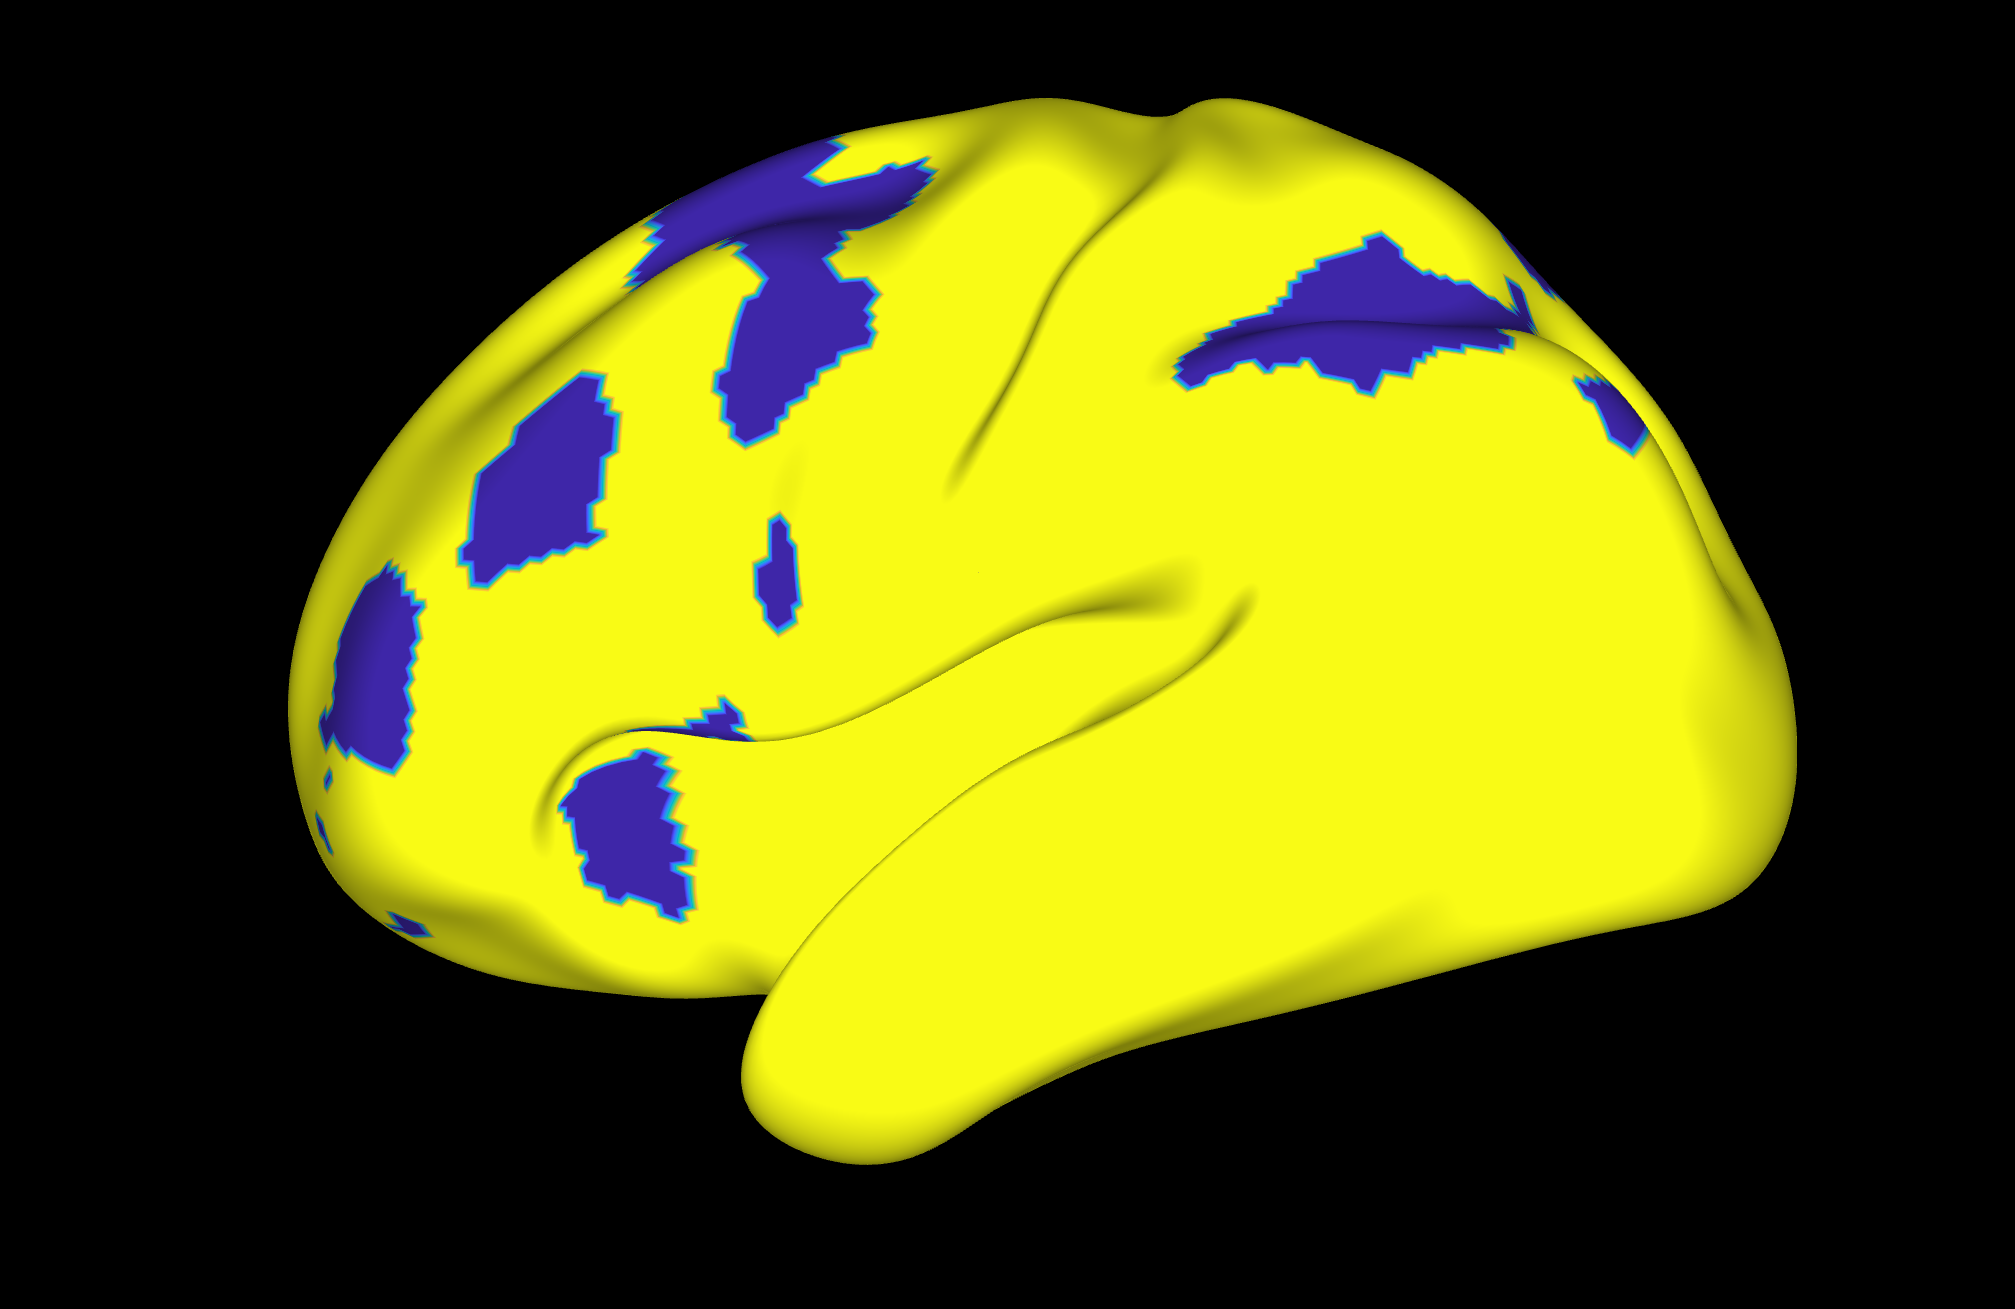

srfplot(hcp_srf.lh, lower_set2)